Consider Lorentz system


$$\dot{x}=\sigma(y-x),\\
\dot{y}=\rho x-y-xz,\\
\dot{z}=-\beta z+xy.$$


We fix the parameters as the standard choice $\sigma=10,\rho=28$ and $\beta=8/3$. The origin is a saddle point with real eigenvalues that is approximately $-22.828$, $-2.667$ and 11.828 [1]. So there is a one-dimensional unstable manifold of the origin. Next, we apply SSMTool to compute the unstable SSM and the associated reduced dynamics on the SSM.

[1] Krauskopf, Bernd, et al. "A survey of methods for computing (un) stable manifolds of vector fields." *International Journal of Bifurcation and Chaos* 15.03 (2005): 763-791.

clear all;

Build model

In SSMTool, the setup of first-order autonomous systems is given as follows


$$\mathbf{B}\dot{\mathbf{z}}=\mathbf{A}\mathbf{z}+\mathbf{F}(\mathbf{z})$$


For the Lorenz system, we have $\mathbf{B}=\mathbf{I}$,


$$\mathbf{A}=\left(\begin{array}{ccc}-\sigma & \sigma & 0\\
\rho & -1 & 0 \\
0 & 0 & -\beta\end{array}\right),\quad \mathbf{F}= \left(\begin{array}{c}0 \\ -xz\\ xy\end{array}\right)$$


sigma = 10;
rho   = 28;
beta  = 8/3;
[A,B,F] = build_model(sigma,rho,beta);

Dynamical system setup

DS = DynamicalSystem();
set(DS,'A',A,'B',B,'fnl',F);

Linear Modal analysis and SSM computation

[V,D,W] = DS.linear_spectral_analysis();


 The first 3 eigenvalues are given as 
       11.828
      -2.6667
      -22.828



S = SSM(DS);
set(S.Options,'paramStyle','graph','reltol',0.5)
masterModes = 1;                        % master mode
order = 5;                              % SSM expansion order
S.choose_E(masterModes);

sigma_out = -1
sigma_in = -1


[W0,R0] = S.compute_whisker(order);     % compute of SSM

Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 5.34E-03 MB
Computing autonomous whisker at order 3
0 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 8.03E-03 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 9.43E-03 MB
Computing autonomous whisker at order 5
0 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.09E-02 MB


Given no inner resonances are detected, the reduced dynamics is linear: $\dot{p}=\lambda_1p$.

Visualization of the unstable SSM

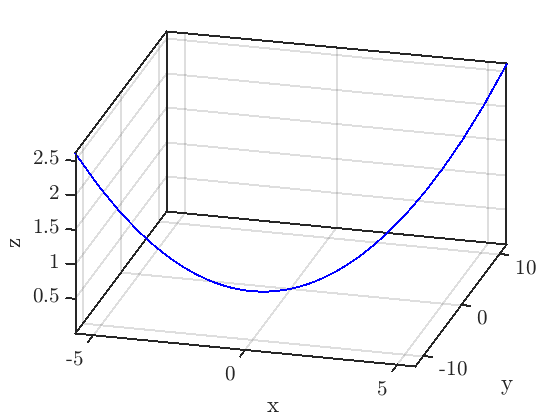

% dynamics on SSM
lamdMaster = D(masterModes,masterModes);
t  = linspace(0,1,100);
p1 = 1e-4*exp(lamdMaster*t); 
% mapping to full system
z1 = reduced_to_full_traj(t,p1,W0);
% repeat the above for different initial condition
p2 = -1e-4*exp(lamdMaster*t);
z2 = reduced_to_full_traj(t,p2,W0);
z  = [z2(:,end:-1:1) z1];
% plot SSM
figure;
plot3(z(1,:),z(2,:),z(3,:),'b-','LineWidth',1.5); grid on
xlabel('x'); ylabel('y'); zlabel('z');
set(gca,'fontsize',16);
set(gca,'LineWidth',1.5);
box on; view([15,35])
axis tight

To validate the obtained SSM, we integrate the Lorenz system with initial conditions along the unstable subspace.

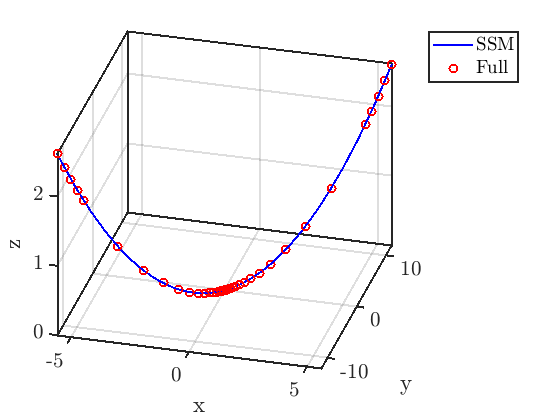

% forward simulation of the original system
zinit_plus = V(:,1)*1e-4;
zinit_minu = -zinit_plus;
odefunc = @(t,x) lorenz(x,sigma,rho,beta);
[tplus,zplus] = ode45(odefunc,[0,1],zinit_plus);
[tminu,zminu] = ode45(odefunc,[0,1],zinit_minu);
zfull = [zminu(end:-1:1,:);zplus];
% plot simulated orbits
hold on
plot3(zfull(:,1),zfull(:,2),zfull(:,3),'ro','LineWidth',1.5);
legend('SSM','Full')